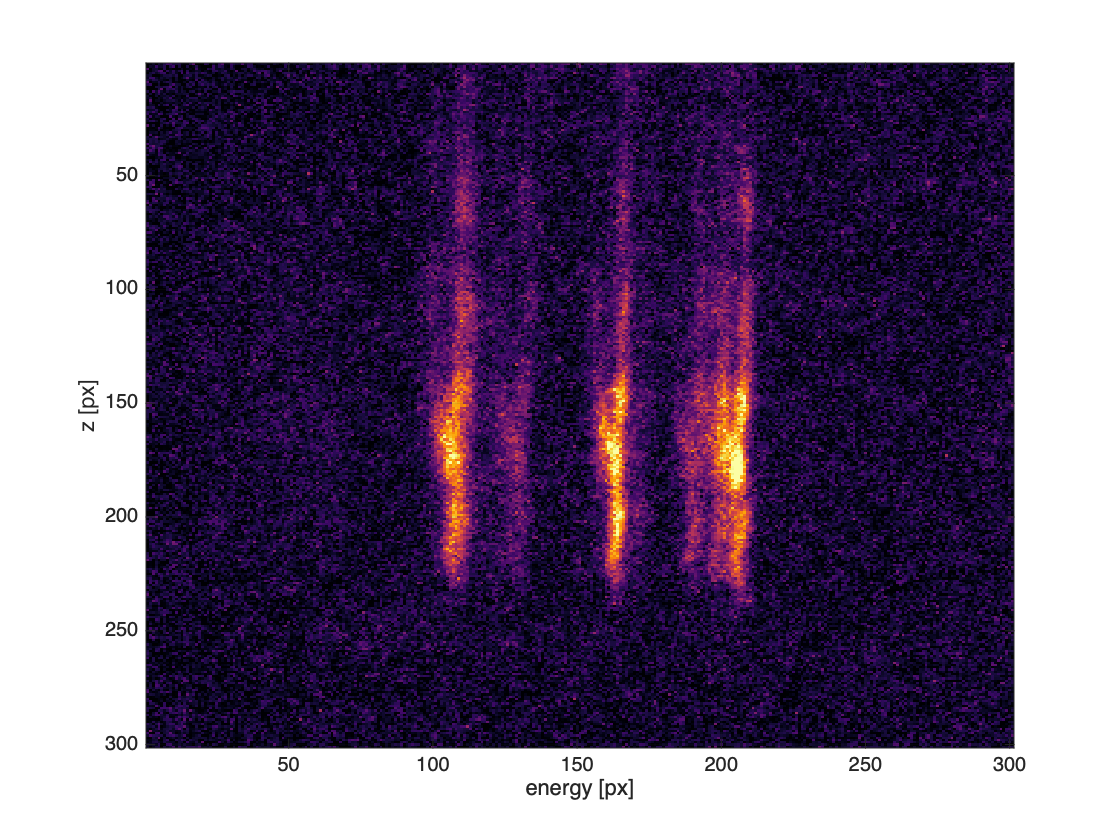

clc; close all; clear;

inPath = checkDir('/Users/rishabhdatta/Dropbox (MIT)/PUFFIN group/Data/Z/MARZ/Shots/MARZ1_z3697/ImagePlate/XRS3-AR/'); 
fname = 'z3697_XRS3-AR.IPH.tif';

img = imread([inPath fname]); 

[img, ~] = imcrop(img,[1400 580+60 300 300]);
figure
imagesc(img);

colormap(inferno())
xlabel('energy [px]'); ylabel('z [px]')
caxis([2500 4000])

grid();

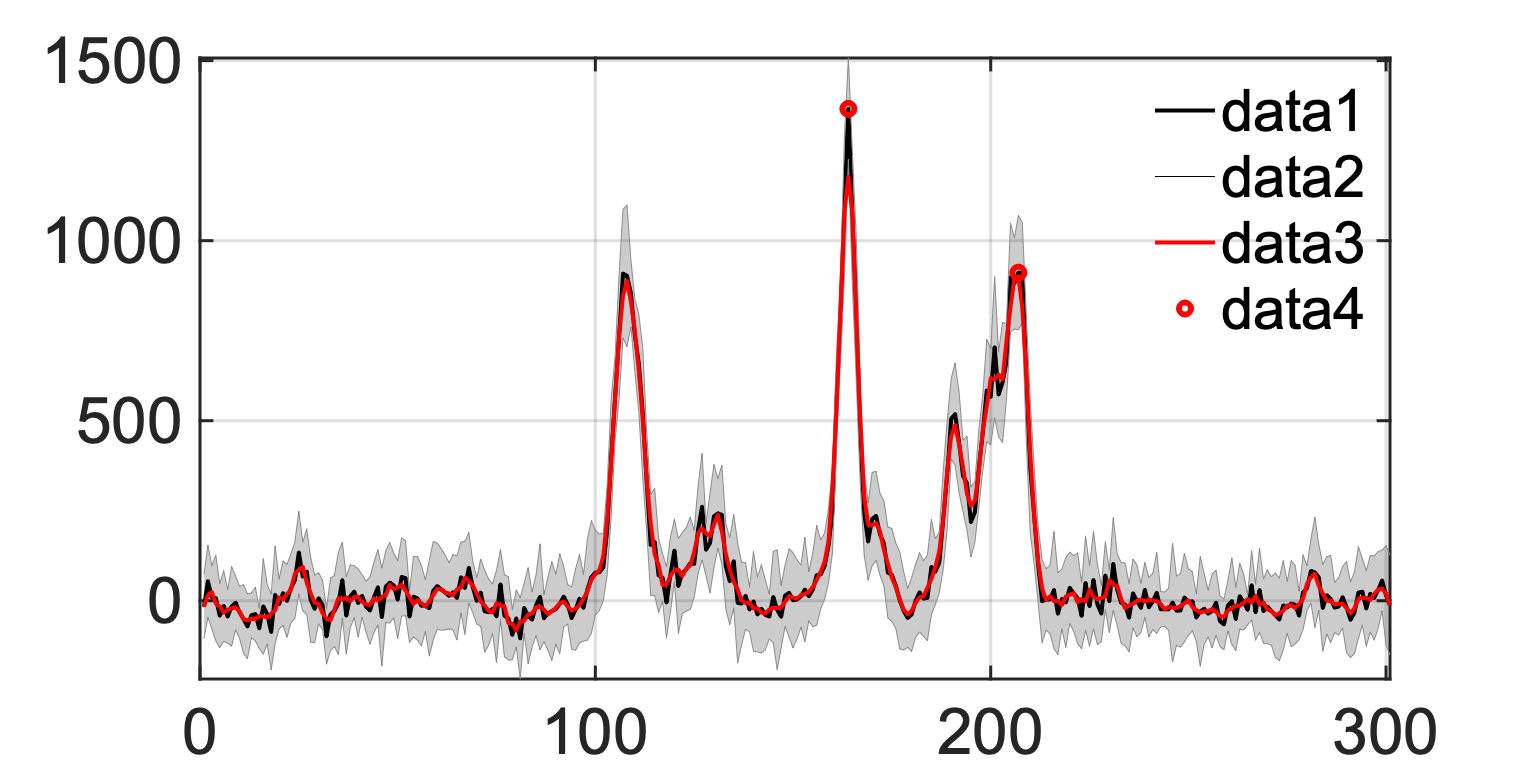

% calibrate

% get lineout

Iout = double(img(200:210,:)); % average over 10 px
Iout_mean = mean(Iout,1);
Iout_mean = repmat(Iout_mean,size(Iout,1),1);
Iout_std = sqrt(1/size(Iout,1) * sum((Iout - Iout_mean).^2,1)); % counts
Iout = mean(Iout,1);

% zero
Iout = Iout - mean(Iout(1:80)); 

figure
plot(Iout,'k','Linewidth',2); hold on;
shadedErrorBar(1:numel(Iout),Iout,Iout_std,'lineProps',{'k'});
grid on; 
formatPlots(900,2);

% smooth Iout

Iout_smooth = smooth(Iout,3);

plot(Iout_smooth,'r','Linewidth',2);

% calibrate
[~,idx] = findpeaks(Iout_smooth,'Npeaks',3,'MinPeakHeight',800);
hold on;
plot(idx(2:end),Iout(idx(2:end)),'or',LineWidth=3); 

idx = idx(2:end); 

figure
E = sort([1598.3,1588.3]);
idx = sort(idx);
plot(idx,E,'O',linewidth=3);

xlabel('px'); ylabel('photon energy [eV]');

P = polyfit(idx,E,1);
xx = 1:numel(Iout);
yy = polyval(P,xx);

px2eV = @(px) polyval(P,px)

px2eV = function_handle with value:
    @(px)polyval(P,px)


eV2px = @(eV) (eV - P(2)) / P(1)

eV2px = function_handle with value:
    @(eV)(eV-P(2))/P(1)


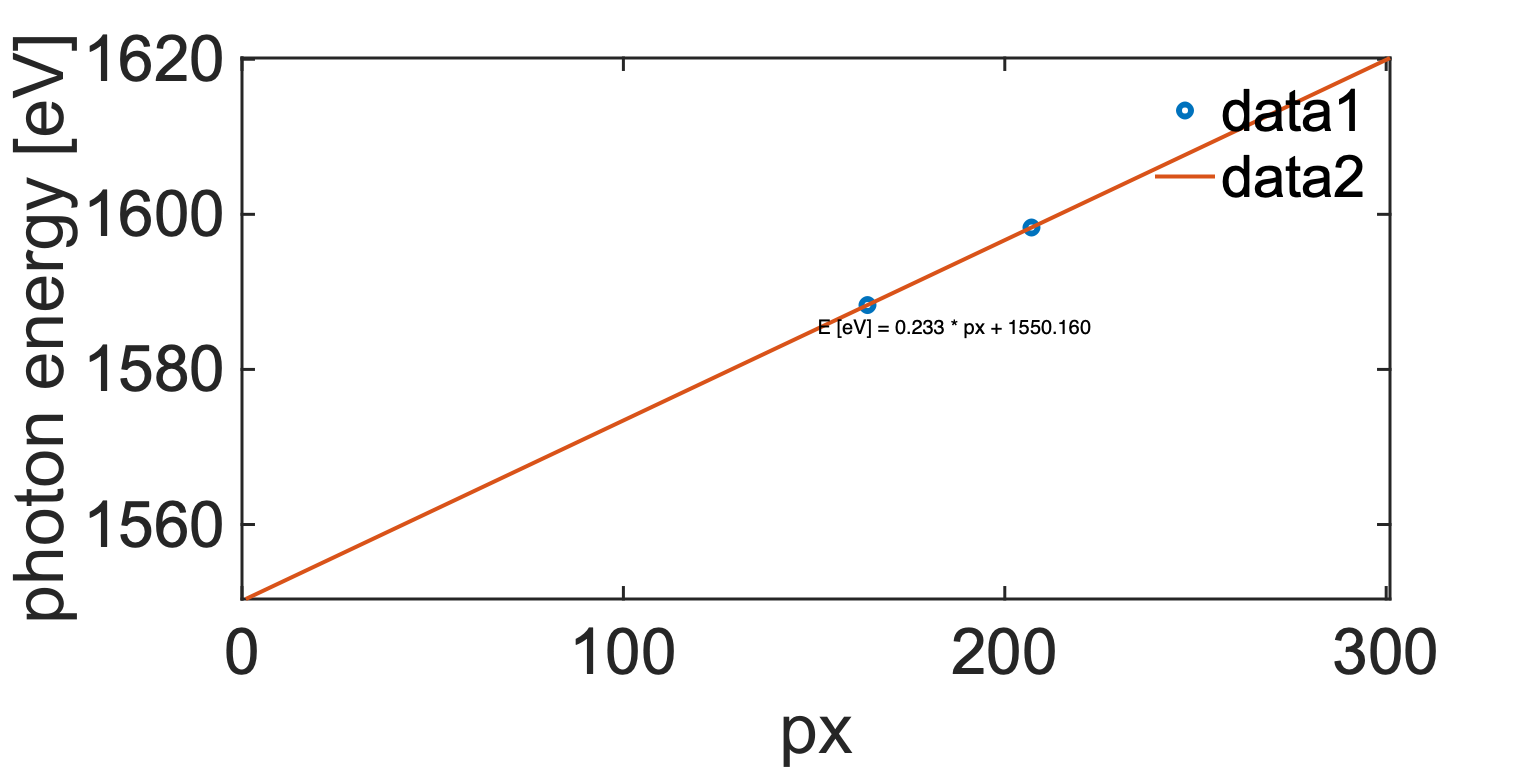


hold on;

plot(xx,yy,'LineWidth',2); 

str = sprintf('E [eV] = %2.3f * px + %2.3f',P(1),P(2));  
text(mean(xx),mean(yy),str);

formatPlots(900,2); 

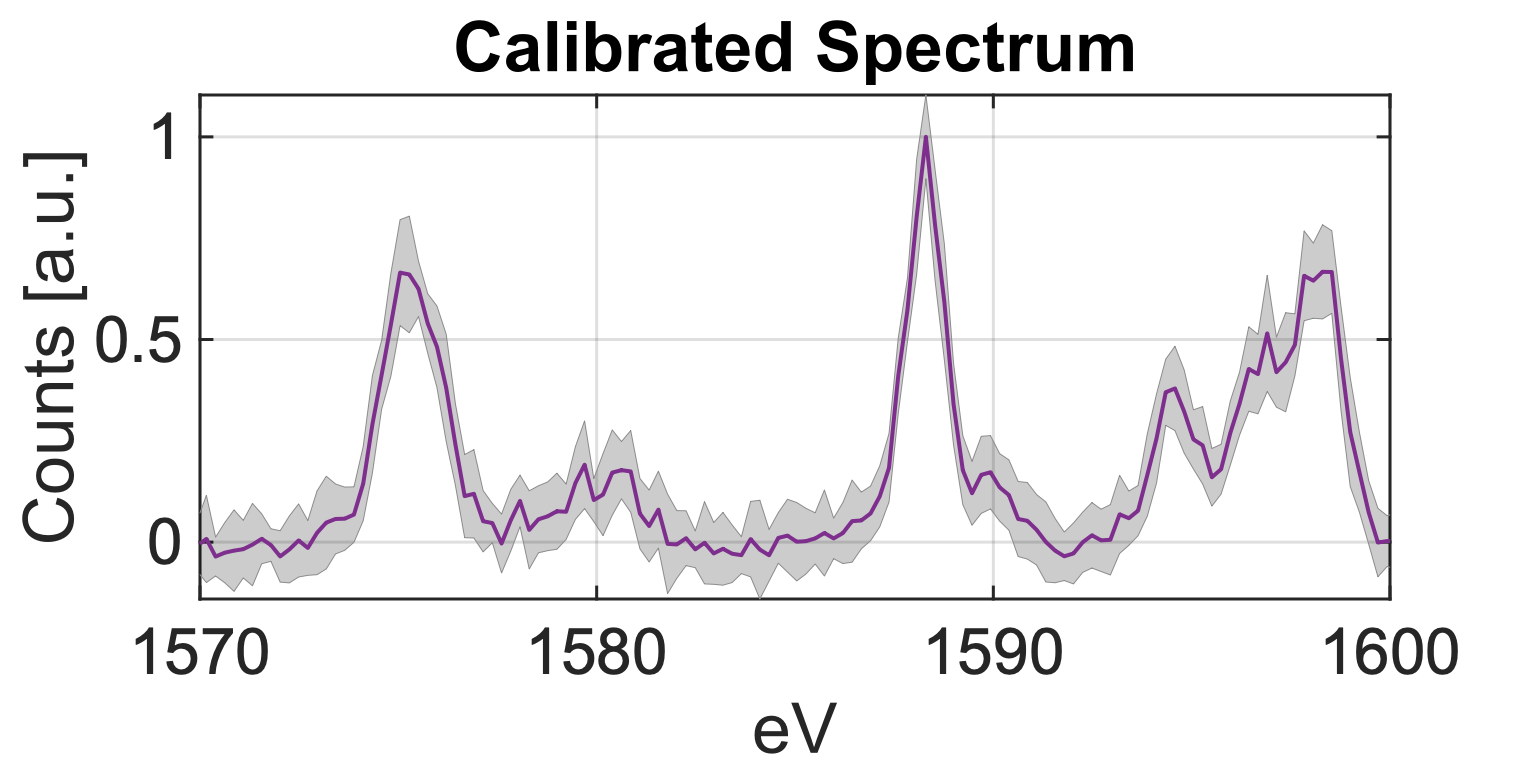


figure
shadedErrorBar(yy,Iout/max(Iout),Iout_std/max(Iout),'lineProps',{'k'}); hold on;
plot(yy,Iout/max(Iout),'Linewidth',2);

grid on; 
xlabel('eV');
formatPlots(900,2);
xlim([1570,1600]);
ylabel('Counts [a.u.]');
% ylim([-100,2000])
legend('off');
title('Calibrated Spectrum')

% save the sepctrum

savePath = checkDir('\Users\rdatta\Dropbox (MIT)\PUFFIN\Data\MARZ\XRS3\');

data = [yy', Iout', Iout_std'];
save([savePath 'z3697_z=-10mm.mat'],'data');
writematrix(data,[savePath 'z36971_z=-10mm.csv']) 

# Plot together

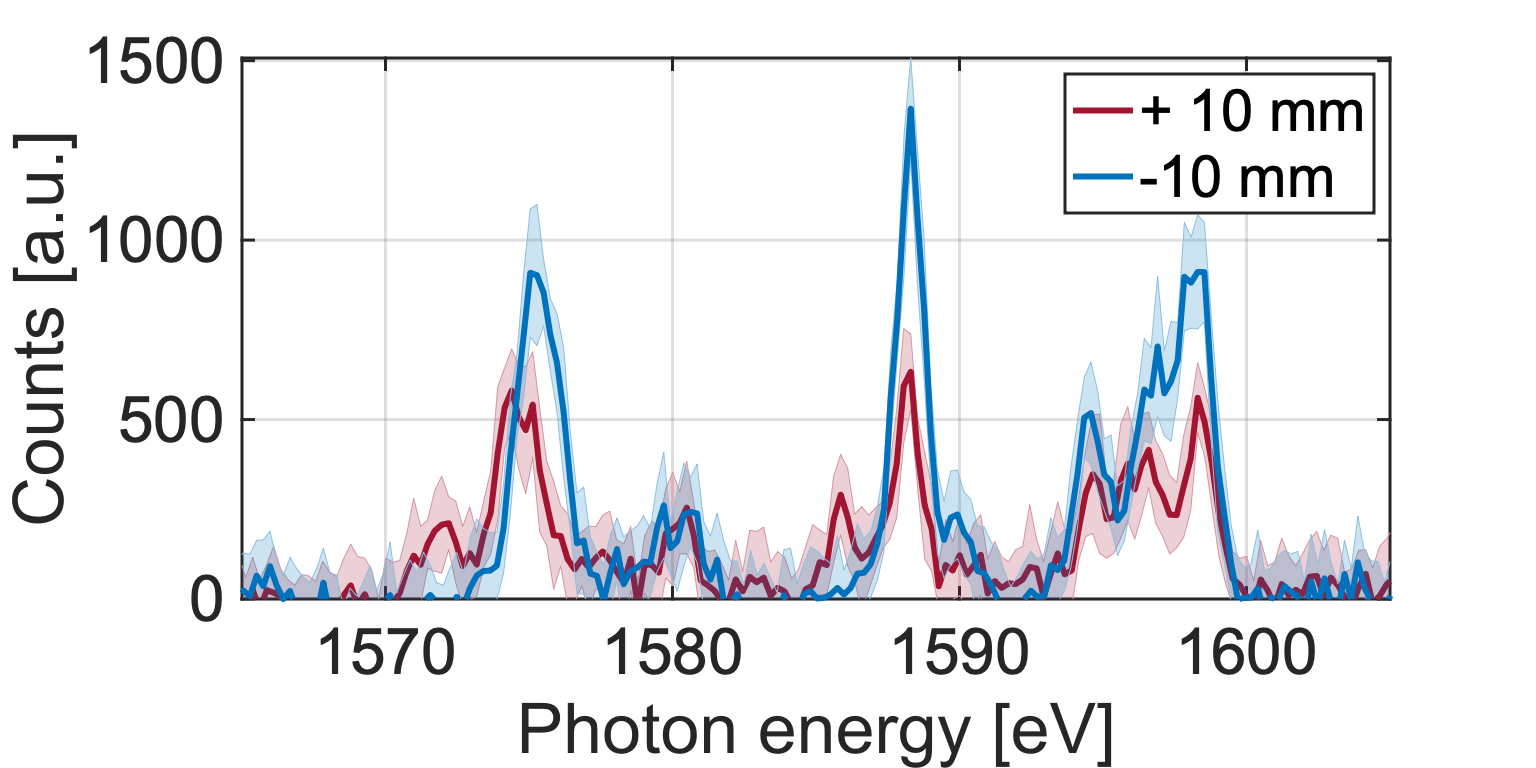


savePath = checkDir('/Users/rishabhdatta/Dropbox (MIT)/PUFFIN/Data/MARZ/XRS3/');
load([savePath 'z3697_z=10mm.mat'],'data');

figure
shadedErrorBar(data(:,1),data(:,2),data(:,3),'lineProps',{'color','#A2142F','HandleVisibility','off'}); hold on;
plot(data(:,1),data(:,2),'Linewidth',3,"Color",'#A2142F','DisplayName','+ 10 mm');

load([savePath 'z3697_z=-10mm.mat'],'data');


shadedErrorBar(data(:,1),data(:,2),data(:,3),'lineProps',{'color','#0072BD','HandleVisibility','off'}); hold on;
plot(data(:,1),data(:,2),'Linewidth',3,"Color",'#0072BD','DisplayName','-10 mm');

grid on; 
xlabel('eV');
formatPlots(900,2);
xlim([1565,1605]);
ylabel('Counts [a.u.]');
xlabel('Photon energy [eV]')
ylim([0,inf])
legend('box','on',"Location",'northeast');

savePath = checkDir('/Users/rishabhdatta/Dropbox (MIT)/PUFFIN/Data/MARZ/Figures_POP/');
saveas(gcf,[savePath 'z3697_XRS3_Lineouts.png']);

# Spectral modulations vs z

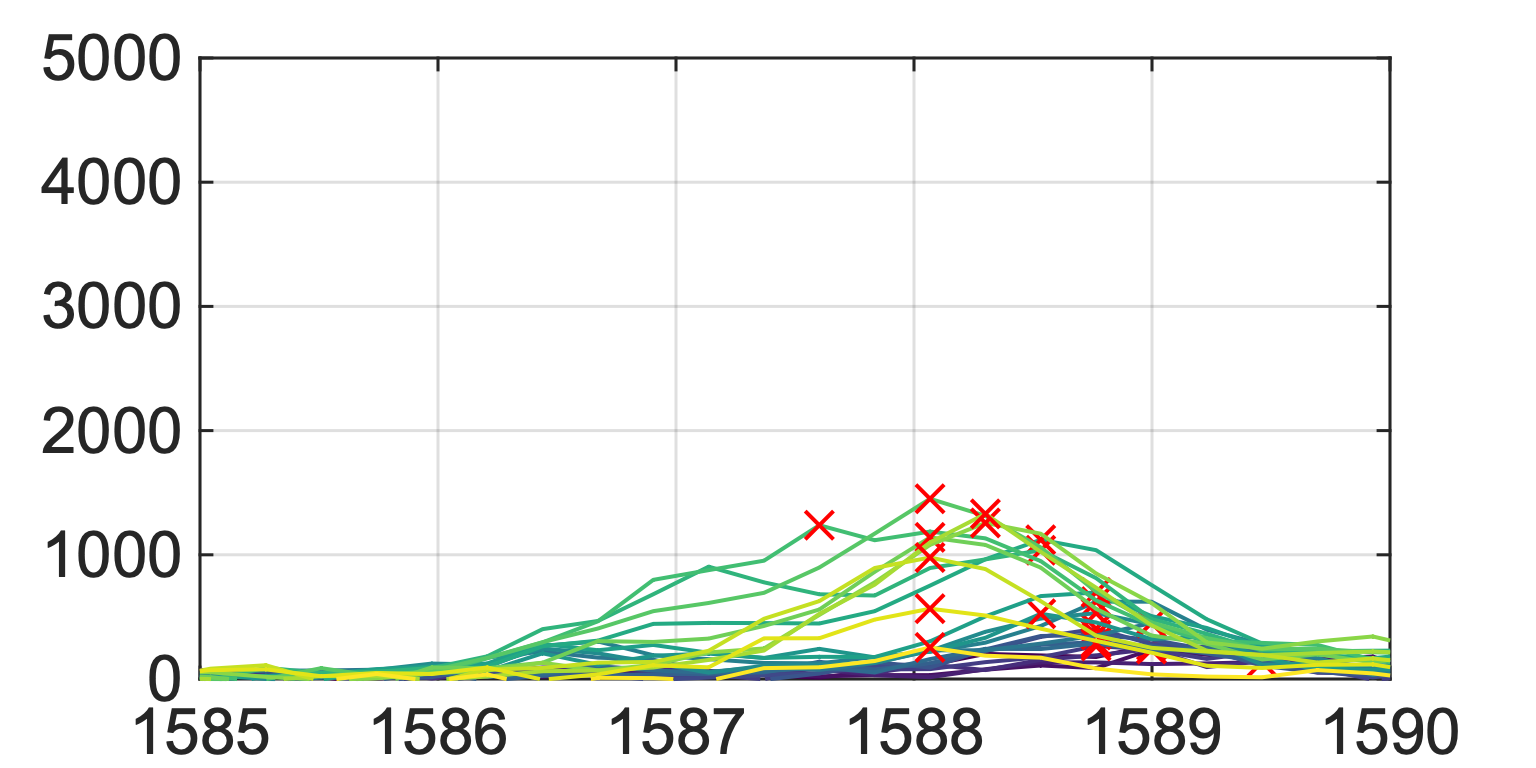



figure
% Get spectra at different z values
Z = 1:10:240;

colors = viridis(numel(Z));

peak_pos = [];

for ii = 1:numel(Z)
    Iout = img(Z(ii):Z(ii)+10,:); % average over 10 px
    Iout = mean(Iout,1);
    % zero
    Iout = Iout - mean(Iout(1:80));
    
    % find IC peak position
    idx = (yy <= 1592) & (yy >= 1585);
    Y = Iout(idx); X = yy(idx);
    [pk,pos] = max(Y);

    %     % find IC peak position
%     idx = (yy <= 1592) & (yy >= 1585);
%     Y = Iout(idx); X = yy(idx);
%     [pk,pos] = max(Y);
    
    
    plot(yy,Iout,'Linewidth',2,"Color",colors(ii,:),'DisplayName',['z [px] = ' num2str(Z(ii)-1)]); hold on;
    plot(X(pos),Y(pos),'rX','HandleVisibility','off',markersize=20,linewidth=2);
    
    peak_pos = [peak_pos; X(pos)]; % eV
    
end

formatPlots(900,2); legend("off");
xlim([1585,1590]); grid(); ylim([0,5000])

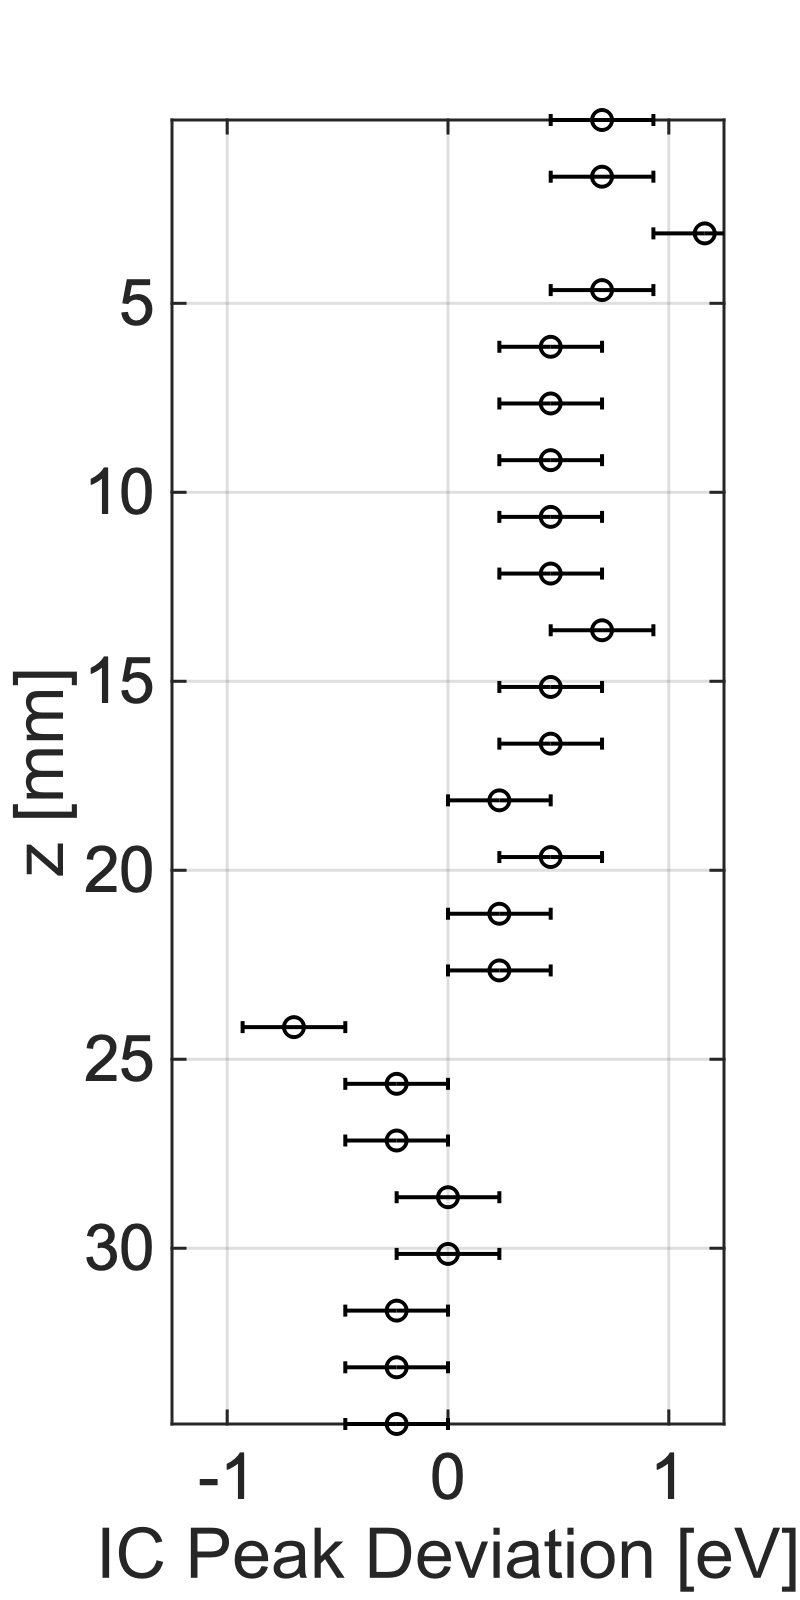

mm2px = (21+15)/240; % mm/px
Z_mm = Z * mm2px;

figure
nominal = 1588.3;
dev = peak_pos-nominal; % eV
plot(dev,Z_mm,'ok',"MarkerSize",10,'HandleVisibility','off',"LineWidth",2); hold on;
errorbar(peak_pos-nominal,Z_mm,max(diff(yy))*ones(size(Z)),'horizontal','Color','k','LineWidth',2,'LineStyle','none');
ylabel('z [mm]'); xlabel('IC Peak Deviation [eV]');
formatPlots(900,0.5); grid; xlim([-1.25,1.25]); legend('off'); ylim([min(Z_mm),max(Z_mm)]);
set(gca, 'Ydir', 'reverse')

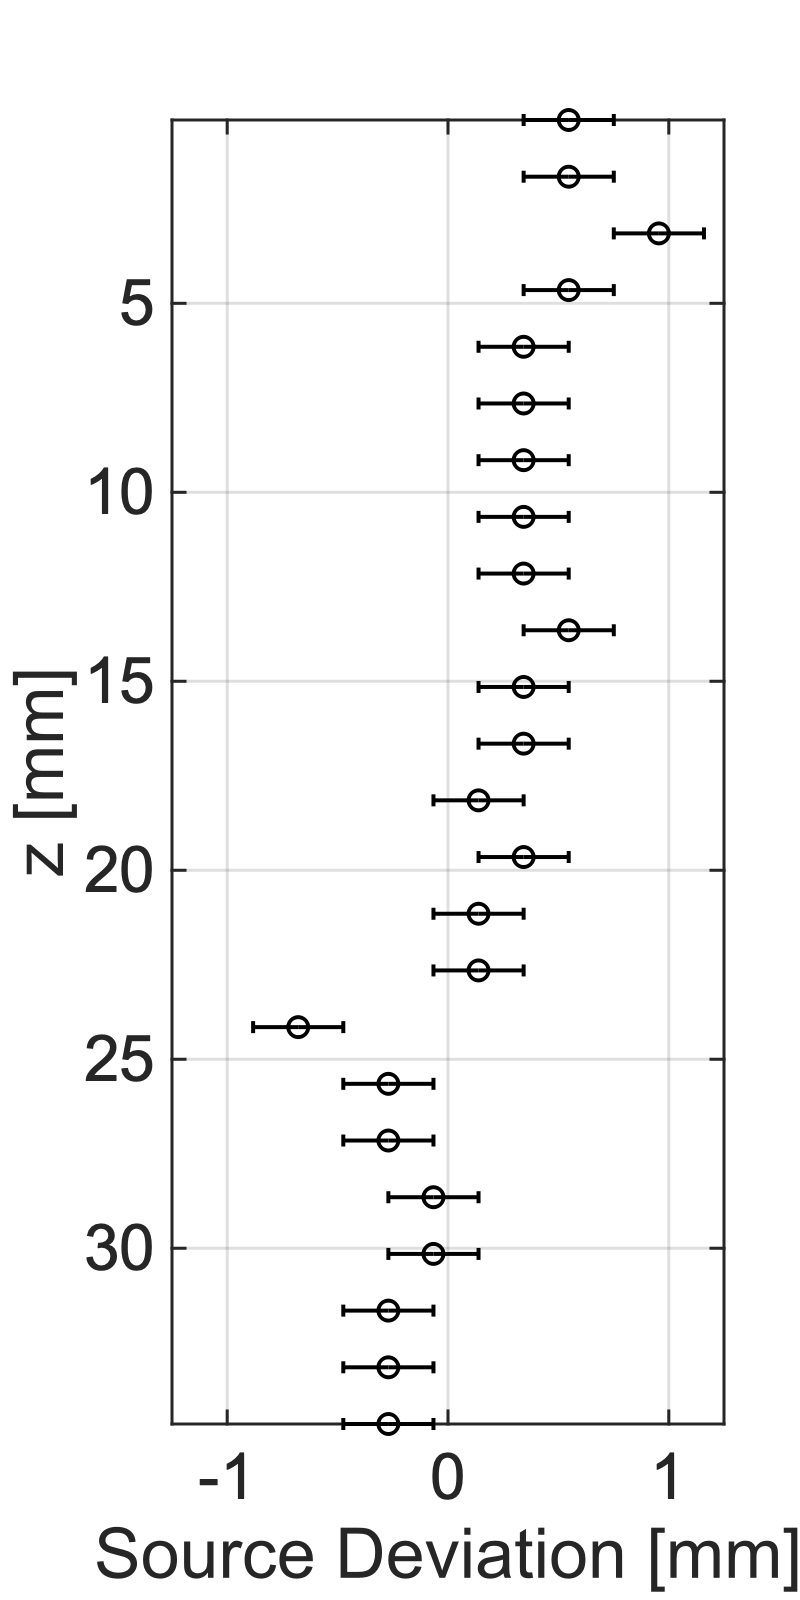

dev_mm = (dev - 0.075) / 1.139; % [mm]
figure
plot(dev_mm,Z_mm,'ok',"MarkerSize",10,'HandleVisibility','off',"LineWidth",2); hold on;
errorbar(dev_mm,Z_mm,max(diff(yy)/1.139)*ones(size(Z)),'horizontal','Color','k','LineWidth',2,'LineStyle','none');
ylabel('z [mm]'); xlabel('Source Deviation [mm]');
formatPlots(900,0.5); grid; xlim([-1.25,1.25]); legend('off'); ylim([min(Z_mm),max(Z_mm)]);
set(gca, 'Ydir', 'reverse')

# Calibrated Image (Pop)


% PRL

savePath = checkDir('/Users/rishabhdatta/Dropbox (MIT)/PUFFIN/Data/MARZ/Figures_POP/')

savePath = '/Users/rishabhdatta/Dropbox (MIT)/PUFFIN/Data/MARZ/Figures_POP/'

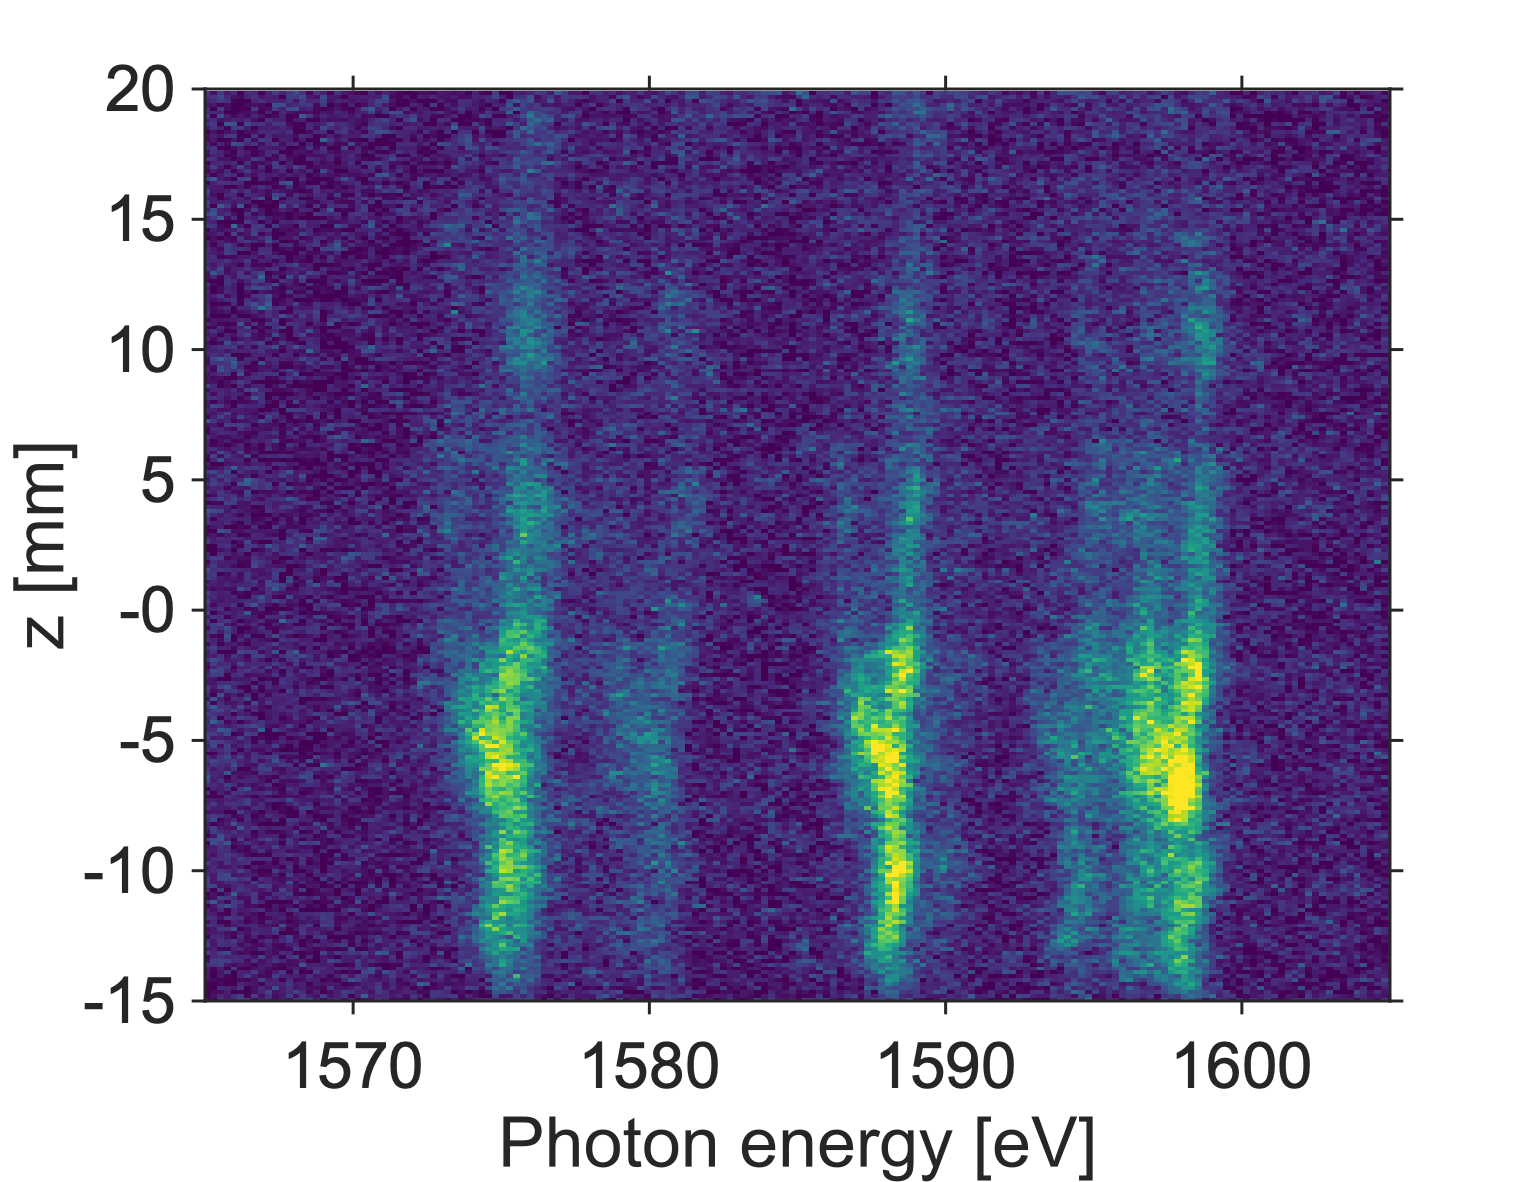

figure
imagesc(img); hold on;
formatPlots()
colormap('viridis')
xlabel('Photon energy [eV]'); ylabel('z [mm]')
caxis([2500 4000])
E_vals = 1560:10:1610; % eV
% convert to px
x_px_vals = eV2px(E_vals);
xticks(x_px_vals);
xticklabels(E_vals); 
set(gca,'TickDir','out');
xlim([eV2px([1565,1605])])
% y-axis
Z_px = 1:size(img,1);
Z_mm = Z_px * mm2px;


Zvals = 0:5:35; % mm
Z_px = Zvals / mm2px; % px
yticks(Z_px);
yticklabels(-1*(Zvals-20));

ylim([min(Z_px),max(Z_px)])
formatPlots(900,1.3)


% Plot centroid on image

% plot(eV2px(peak_pos(1:end-2)),Z(1:end-2),'x',"MarkerSize",10,'Color',[1 0.3 0.3],'HandleVisibility','off',"LineWidth",1.5); hold on;
saveas(gcf,[savePath, 'z3697_xrs3.png'])

% errorbar(eV2px(peak_pos),Z,max(diff(eV2px(yy)))*ones(size(Z)),'horizontal','Color','r','LineWidth',1,'LineStyle','none');



# For APS

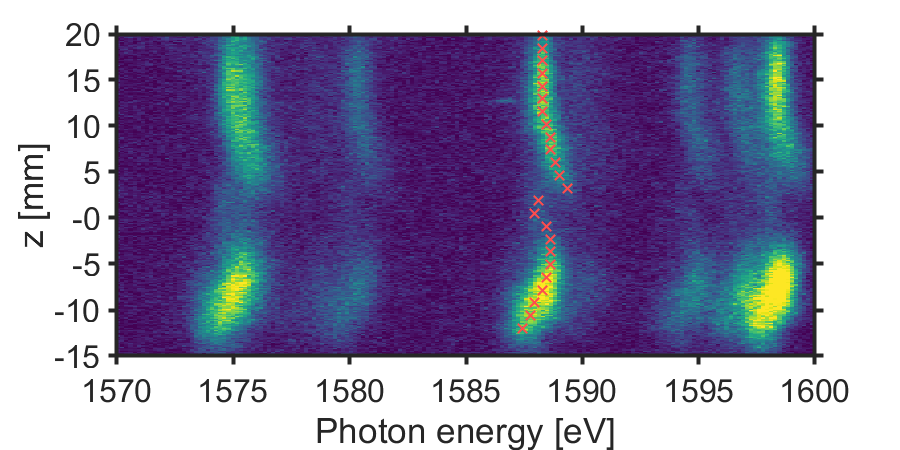


% PRL


figure
imagesc(img); hold on;
formatPlots()
colormap('viridis')
xlabel('Photon energy [eV]'); ylabel('z [mm]')
caxis([2500 5000]);
E_vals = 1570:5:1600; % eV
% convert to px
x_px_vals = eV2px(E_vals);
xticks(x_px_vals);
xticklabels(E_vals); 
set(gca,'TickDir','out');
xlim([eV2px([1570,1600])])
% y-axis
Z_px = 1:size(img,1);
Z_mm = Z_px * mm2px;


Zvals = 0:5:35; % mm
Z_px = Zvals / mm2px; % px
yticks(Z_px);
yticklabels(-1*(Zvals-20));

ylim([min(Z_px),max(Z_px)])
formatPlots(900,2)


% Plot centroid on image

plot(eV2px(peak_pos(1:end-2)),Z(1:end-2),'x',"MarkerSize",10,'Color',[1 0.3 0.3],'HandleVisibility','off',"LineWidth",1.5); hold on;

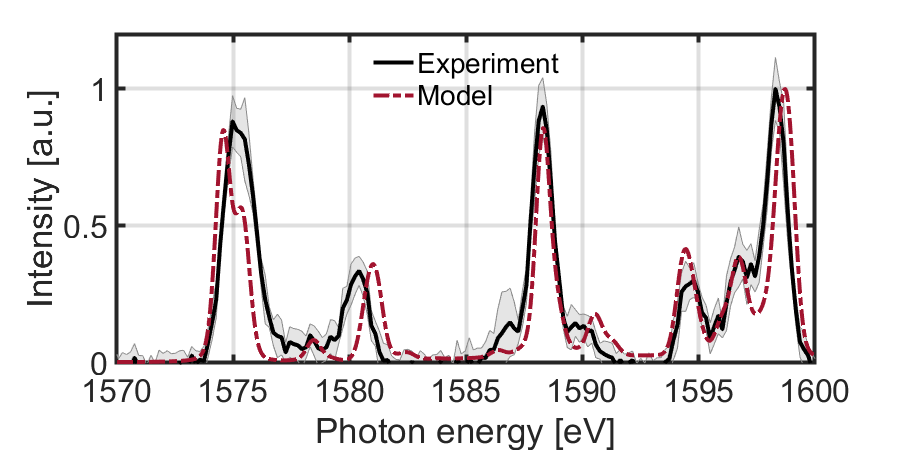


figure
exp = dlmread("z3781_exp.txt");
pred = dlmread("z3781_pred.txt");

load exp_data.mat data

% plot(exp(:,1),exp(:,2),"DisplayName",'Experiment',"LineWidth",3,'Color','k'); hold on;
shadedErrorBar(data(:,1),data(:,2),data(:,3),'lineProps',{'k',"HandleVisibility",'off'},'patchSaturation',0.1); hold on;
plot(data(:,1),data(:,2),"DisplayName",'Experiment',"LineWidth",3,'Color','k'); hold on;
plot(pred(:,1),pred(:,2)/max(pred(:,2)),'-.',"DisplayName",'Model',"LineWidth",3,'Color','#A2142F'); hold on;
xlabel('Photon energy [eV]');
ylabel('Intensity [a.u.]');
xlim([1570,1600]);
formatPlots(900,2); grid on;
ylim([0,1.2])
legend('location','north')

% set(gcf,'Position',[0 0 900 350])
% legend('off');
% saveas(gcf,[savePath, 'z3781_xrs3_lineout.png']);
